# Generering av variabler

n=20e3;
x=rand(1,n);
y=rand(1,n);

x_std_normal=sqrt(-2*log(x)).*cos(2*pi*y);
y_std_normal=sqrt(-2*log(x)).*sin(2*pi*y);

mu1=1;
mu2=2;

x_rician=mu1+x_std_normal

x_rician =     1.7946    1.3114   -0.3252    0.3909    0.9629    1.0091    0.4867    0.4083    2.3084    1.3807   -0.4133    2.0442    0.8354    1.6660   -0.0712    0.2828    1.8405    1.4608    2.8222    1.7023   -0.0072    1.7671   -0.1847    0.9842   -0.4351    1.2925    0.4060    1.6762   -0.7265    0.6182    2.3977    0.7954    2.5054   -0.2859    0.8102    1.4394    0.6769   -0.4957    1.3553   -1.2134    1.4617    2.1270    1.7827    1.9684   -0.5372    0.8443    1.4716    1.8274   -1.1173    1.5385


y_rician=mu2+y_std_normal

y_rician =     1.9657    1.1840    2.0351    0.4122    3.6514    1.7720    2.1505    1.8463    3.2608    1.9140    3.3763    2.3368    1.8195    2.2755    3.2629    3.5318    3.2395    1.4881    0.7651    2.3271    1.2143    0.9012    1.2230    3.2079    1.8698    2.3418    1.7221    2.5450    1.0434    1.3452    1.7249    3.2150    2.4767    1.4333    1.7650    2.0829    2.2565    2.0495    2.6988    1.3416    2.0813    2.5413    3.8712    1.7974   -0.5537    2.3252    0.7996    1.0549    2.7184    1.5539



z_rayleigh=sqrt(x_std_normal.^2+y_std_normal.^2);
z_rician=sqrt(x_rician.^2+y_rician.^2);

# Histogramer

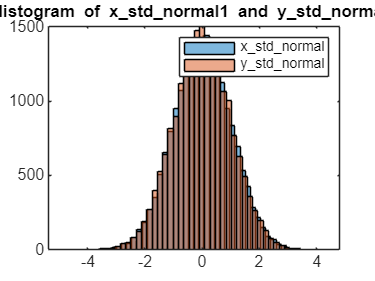

figure;
histogram(x_std_normal, 50, 'FaceAlpha', 0.5);
hold on;
histogram(y_std_normal, 50, 'FaceAlpha', 0.5);
title('Histogram of x\_std\_normal1 and y\_std\_normal1');
legend('x\_std\_normal', 'y\_std\_normal');
hold off;

Observasjoner: 

To normalfordelte variabler.

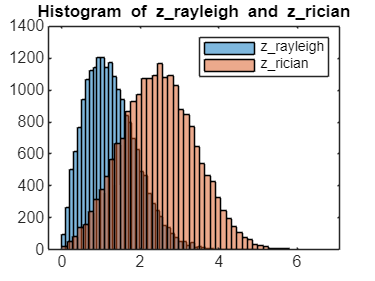

% Histogram for z_rayleigh og z_rician
figure;
histogram(z_rayleigh, 50, 'FaceAlpha', 0.5);
hold on;
histogram(z_rician, 50, 'FaceAlpha', 0.5);
title('Histogram of z\_rayleigh and z\_rician');
legend('z\_rayleigh', 'z\_rician');
hold off;

Observasjoner:

Rayleigh: modelering av signal amplitude ved multipath fading.

Rician: modelering av signal amplitude ved line-of-sight og multipath fading.

# BPSK

symbols = 2 * (randi([0, 1], 1, n) - 0.5);

sigma_squared = [0.1, 0.1259, 0.1585, 0.1995, 0.2512, 0.3162, 0.3981, 0.5012, 0.6310, 0.7943, 1];
sigma = sqrt(sigma_squared);

N = 10 * log10(1 ./ sigma_squared);

## Gaussisk

% Preallocate BER array
ber_gaus = zeros(1, length(sigma_squared));

for i = 1:length(sigma)
    % Generate Gaussian noise with desired variance
    x_i = sigma(i) * x_std_normal;
    
    % Add noise to the symbols
    received_signal = symbols + x_i;
    
    % Decode by rounding to nearest constellation point
    decoded_symbols = sign(received_signal);
    
    % Calculate number of errors
    errors = sum(decoded_symbols ~= symbols);
    
    % Compute Bit Error Rate (BER)
    ber_gaus(i) = errors / n;
end

## Rayleigh

% Preallocate BER array
ber_rayleigh = zeros(1, length(sigma_squared));

for i = 1:length(sigma_squared)
    % Generate Gaussian random variables with variance sigma_squared(i)
    sigma = sqrt(sigma_squared(i));
    x_i = sigma * x_std_normal;
    y_i = sigma * y_std_normal;
    
    % Generate Rayleigh random variables
    z_rayleigh = sqrt(x_i.^2 + y_i.^2);
    
    % Add Rayleigh noise to symbols
    received_signal_rayleigh = symbols + z_rayleigh;
    
    % Decode by rounding to nearest constellation point
    decoded_symbols_rayleigh = sign(received_signal_rayleigh);
    
    % Calculate number of errors
    errors_rayleigh = sum(decoded_symbols_rayleigh ~= symbols);
    
    % Compute Bit Error Rate (BER)
    ber_rayleigh(i) = errors_rayleigh / n;
end

## Plot BER vs. N

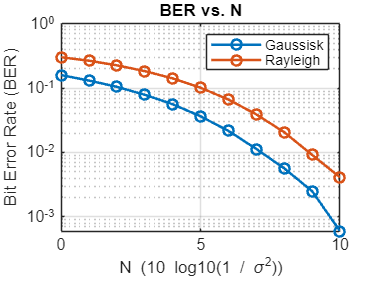

% Plot BER vs variance
figure;
semilogy(N, ber_gaus, '-o', 'LineWidth', 1.5);
hold on;
semilogy(N, ber_rayleigh, '-o', 'LineWidth', 1.5);
grid on;
title('BER vs. N');
xlabel('N (10 log10(1 / \sigma^2))');
ylabel('Bit Error Rate (BER)');
legend("Gaussisk","Rayleigh");
hold off;

## Observasjoner

BER er generelt høyere for Rayleigh sammenlignet med gaussisk støy.

Synkende varians, eller økende N, medfører synkende BER, grunnet lavere støyeffekt.